A = zeros(10);
B = zeros(10);
A(1,1:3) = [5 -4 1];
A(2,1:4) = [-4 6 -4 1];
for m = 3:8
    A(m,m-2:m+2) = [1 -4 6 -4 1];
end
A(9,7:10) = [1 -4 6 -4];
A(10,8:10) = [1 -4 7];
A

A =      5    -4     1     0     0     0     0     0     0     0
    -4     6    -4     1     0     0     0     0     0     0
     1    -4     6    -4     1     0     0     0     0     0
     0     1    -4     6    -4     1     0     0     0     0
     0     0     1    -4     6    -4     1     0     0     0
     0     0     0     1    -4     6    -4     1     0     0
     0     0     0     0     1    -4     6    -4     1     0
     0     0     0     0     0     1    -4     6    -4     1
     0     0     0     0     0     0     1    -4     6    -4
     0     0     0     0     0     0     0     1    -4     7



B(1,1:2) = [2 -1];
B(10,9:10) = [-1 2];
for m = 2:9
    B(m,m-1:m+1) = [-1 2 -1];
end
B

B =      2    -1     0     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0     0
     0     0     0    -1     2    -1     0     0     0     0
     0     0     0     0    -1     2    -1     0     0     0
     0     0     0     0     0    -1     2    -1     0     0
     0     0     0     0     0     0    -1     2    -1     0
     0     0     0     0     0     0     0    -1     2    -1
     0     0     0     0     0     0     0     0    -1     2



[H,T] = stdForm(A,B)

H =     2.5000   -0.8660   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.8660    2.1667   -0.9428   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0000   -0.9428    2.0833   -0.9682    0.0000    0.0000    0.0000         0    0.0000         0
   -0.0000    0.0000   -0.9682    2.0500   -0.9798    0.0000   -0.0000    0.0000         0         0
   -0.0000    0.0000    0.0000   -0.9798    2.0333   -0.9860         0   -0.0000   -0.0000         0
   -0.0000    0.0000    0.0000    0.0000   -0.9860    2.0238   -0.9897    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.9897    2.0179   -0.9922         0         0
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.9922    2.0139   -0.9938    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.9938    2.0111   -0.9950
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.9

T =     0.7071    0.4082    0.2887    0.2236    0.1826    0.1543    0.1336    0.1179    0.1054    0.0953
         0    0.8165    0.5774    0.4472    0.3651    0.3086    0.2673    0.2357    0.2108    0.1907
         0         0    0.8660    0.6708    0.5477    0.4629    0.4009    0.3536    0.3162    0.2860
         0         0         0    0.8944    0.7303    0.6172    0.5345    0.4714    0.4216    0.3814
         0         0         0         0    0.9129    0.7715    0.6682    0.5893    0.5270    0.4767
         0         0         0         0         0    0.9258    0.8018    0.7071    0.6325    0.5721
         0         0         0         0         0         0    0.9354    0.8250    0.7379    0.6674
         0         0         0         0         0         0         0    0.9428    0.8433    0.7628
         0         0         0         0         0         0         0         0    0.9487    0.8581
         0         0         0         0         0         0         0         0       


[eigVal, eigVec] = jacobi(H)

eigVal =     3.0649
    0.9022
    3.8033
    1.9835
    2.5470
    0.1641
    3.4952
    0.4720
    1.4200
    3.9660


eigVec =     0.4455    0.2402    0.2496   -0.4246    0.4623    0.0496   -0.3718   -0.1346   -0.3443   -0.1009
   -0.2906    0.4431   -0.3756   -0.2532   -0.0251    0.1338    0.4273   -0.3153   -0.4294    0.1708
   -0.1324    0.3737    0.4227    0.3409   -0.4145    0.2386   -0.2605   -0.4431   -0.0238   -0.2333
    0.4171    0.0244   -0.3852    0.2817    0.2229    0.3427   -0.0361   -0.4304    0.4018    0.2873
   -0.3012   -0.3407    0.2716   -0.3177    0.2965    0.4238    0.3108   -0.2553    0.2818   -0.3312
   -0.0993   -0.4151   -0.1047   -0.2960   -0.3760    0.4629   -0.4249    0.0234   -0.2240    0.3638
    0.4046   -0.1309   -0.0823    0.3045   -0.0967    0.4476    0.3220    0.2910   -0.4174   -0.3839
   -0.3279    0.2668    0.2526    0.3058    0.4267    0.3745   -0.0556    0.4301   -0.0281    0.3910
   -0.0572    0.4292   -0.3726   -0.2946   -0.1324    0.2502   -0.2386    0.3768    0.3999   -0.3847
    0.3880    0.2118    0.4188   -0.3136   -0.3548    0.0904    0.4114    0.1533  


sortedEigVal = sort(eigVal);

threeMinValue = sortedEigVal(1:3,1).'

threeMinValue =     0.1641    0.4720    0.9022


threeMinValue*11^2

ans =    19.8566   57.1068  109.1663


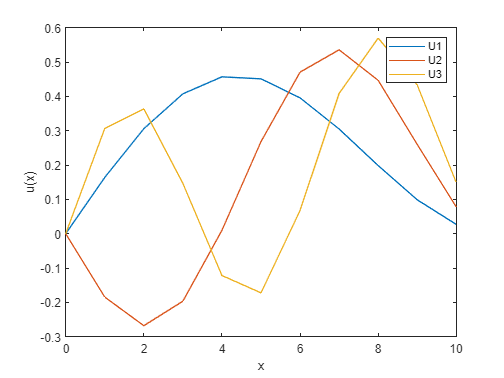


xaxis = 0:10;

u1(1) = 0;
u2(1) = 0;
u3(1) = 0;

L = choleski(B);
eigVec = normc(inv(L).'*eigVec);

for i = 1:10
    u1(i+1) = eigVec(i,find(eigVal == threeMinValue(1)));
    u2(i+1) = eigVec(i,find(eigVal == threeMinValue(2)));
    u3(i+1) = eigVec(i,find(eigVal == threeMinValue(3)));
end

plot(xaxis,u1)
hold on
plot(xaxis, u2)
plot(xaxis, u3)
hold off
xlabel('x')
ylabel('u(x)')
legend('U1','U2','U3')

function [eigVal, eigVec] = jacobi(A)
    maxRot = 5*(size(A,1)^2);
    P = eye(size(A,1));
    for i = 1:maxRot
        [absMax, k,l] = absoluteMaxMatrix(A);
        if absMax < 1.0e-9
            eigVal = diag(A);
            eigVec = P;
            return
        end
        [A,P] = rotate(A,P,k,l);
    end
    error('Too many rotations')
end

function [absMax, k,l] = absoluteMaxMatrix(A)
    absMax = 0;
    for i = 1:size(A,1)-1
        for j = i+1:size(A,1)
            if (absMax <= abs(A(i,j)))
                absMax = abs(A(i,j));
                k = i; l = j;
            end
        end
    end
end

function [A, P] = rotate(A,P,k,l)
    diff = A(l,l) - A(k,k);
    if abs(A(k,l)) < abs(diff)*1.0e-36
        t = A(k,l);
    else
        phi = diff/(2*A(k,l));
        t = 1/(abs(phi) + sqrt(phi^2 + 1));
        if phi < 0; t = -t; end;
    end
    c = 1/sqrt(t*t + 1); s = t*c;
    tao = s/(1 + c);
    temp = A(k,l); A(k,l) = 0;
    A(k,k) = A(k,k) - t*temp;
    A(l,l) = A(l,l) + t*temp;

    for i = 1:k-1
        temp = A(i,k);
        A(i,k) = temp - s*(A(i,l) + tao*temp);
        A(i,l) = A(i,l) + s*(temp - tao*A(i,l));
    end

    for i = k+1:l-1
        temp = A(k,i);
        A(k,i) = temp - s*(A(i,l) + tao*temp);
        A(i,l) = A(i,l) + s*(temp - tao*A(i,l));
    end

    for i = l+1:size(A,1)
        temp = A(k,i);
        A(k,i) = temp - s*(A(l,i) + tao*temp);
        A(l,i) = A(l,i) + s*(temp - tao*A(l,i));
    end

    for i = 1:size(A,1)
        temp = P(i,k);
        P(i,k) = temp - s*(P(i,l) + tao*P(i,k));
        P(i,l) = P(i,l) + s*(temp-tao*P(i,l));
    end
end    

function L = choleski(A)
    L = zeros(size(A));
    eig_vals = eig((A+A')/2);
    is_pd = nnz(eig_vals>0) == length(A);
    if(is_pd ~= 1)
        error('Matrix is not positive definite.')
    end
    for j = 1 : size(A)
        for i = 1 : size(A)
            if(j == 1)
               if (i == 1)
                    L(i,j) = sqrt(A(1,1));
                else
                    L(i,j) = A(i,1) / L(1,1);
               end 
            else
                if(i == j)
                    sumLjk = 0;
                    for k = 1: j-1  
                        sumLjk = sumLjk + L(j,k)*L(j,k);
                        L(j,j) = sqrt(A(j,j) - sumLjk);
                    end
                elseif (i > j)
                    sumLikLjk = 0;
                    for k = 1:j-1
                        sumLikLjk = sumLikLjk + L(i,k)*L(j,k);
                        L(i,j) = (A(i,j) - sumLikLjk)/L(j,j);
                    end
                end
            end
        end
    end
end


function [H,T] = stdForm(A,B)
    try
        L = choleski(B);
    catch ME
        throw(ME)
    end
    T = transpose(inv(L));
    H = L\A*T;
end
